% Convex Optimization:
% Hw5
% Q1-Part C
clear;
clc;
close all;

Solution for different norms with  plot **histograms** of the **Residuals**.

n=30;
m=100;
randn('state',42);
A=randn(m,n);
b=randn(m,1);
%L1.5 solution
cvx_begin
variables x(n) s(m);
s >= abs(A*x-b);
minimize(sum(quad_over_lin(s,sqrt(s),0)))
cvx_end

 
Calling SDPT3 4.0: 930 variables, 500 equality constraints
------------------------------------------------------------

 num. of constraints = 500
 dim. of socp   var  = 600,   num. of socp blk  = 200
 dim. of linear var  = 300
 dim. of free   var  = 30
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|1.1e+01|1.1e+01|6.4e+02| 7.071068e+01| 0:0:00|6.4e+02|1.0e+00|1.0e+00| spchol 1   1
 1|0.678|0.678|6.3e+00|6.7e+00|6.3e+02| 1.634980e+02| 0:0:00|2.5e+02|9.4e-01|5.5e-01| spchol 1   1
 2|0.812|0.812|2.7e+00|2.9e+00|3.


%L2 solution
xl2=A\b;  % Pseudo inverse or AX=B




%L1 solution
cvx_begin
variables xl1(n);
minimize(norm(A*xl1-b,1));
cvx_end

 
Calling SDPT3 4.0: 230 variables, 100 equality constraints
------------------------------------------------------------

 num. of constraints = 100
 dim. of linear var  = 200
 dim. of free   var  = 30
 *** convert ublk to linear blk
********************************************************************************************
   SDPT3: homogeneous self-dual path-following algorithms
********************************************************************************************
 version  predcorr  gam  expon
    NT      1      0.000   1
it pstep dstep pinfeas dinfeas  gap     mean(obj)    cputime    kap   tau    theta
--------------------------------------------------------------------------------------------
 0|0.000|0.000|7.1e+00|7.4e+00|3.4e+02| 7.071068e+01| 0:0:00|3.4e+02|1.0e+00|1.0e+00| chol 1   1
 1|0.856|0.856|4.5e+00|4.7e+00|4.1e+02| 1.476257e+02| 0:0:00|1.0e+02|8.5e-01|5.4e-01| chol 1   1
 2|0.877|0.877|1.0e+00|1.1e+00|8.7e+01| 7.390450e+01| 0:0:00|3.6e+00|9.4e-01|1.3e-01| chol 

r=A*x-b; %residuals [Errors]
rl2=A*xl2-b;
rl1=A*xl1-b;


%Check Optimality Conditions
A'*(3/2*sign(r).*sqrt(abs(r))) % we can drop the 3/2

ans = 	1.0e+-5 *

   -0.0098
    0.2024
   -0.1796
    0.0895
    0.1181
   -0.0907
   -0.0643
    0.0486
   -0.0066
   -0.0151


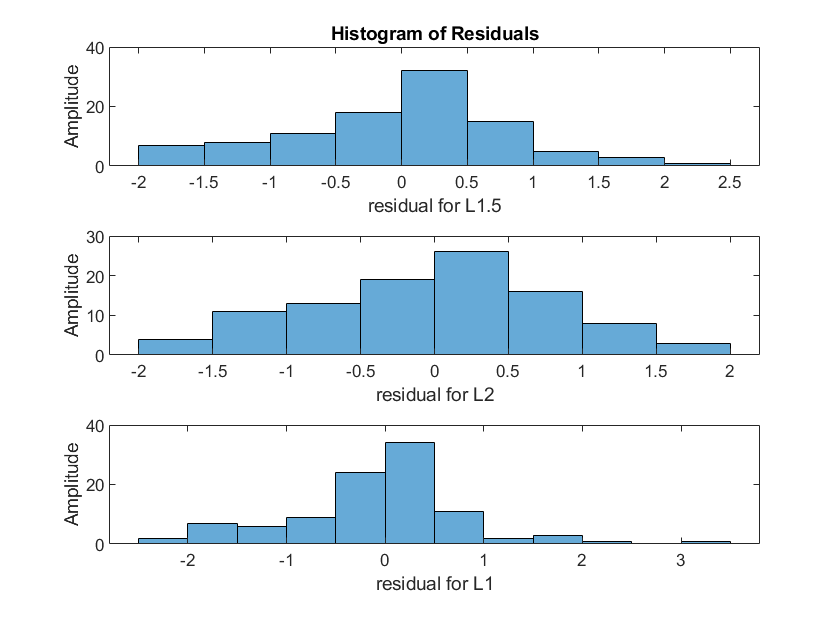


figure()
subplot(3,1,1)
histogram(r)

title('Histogram of Residuals')
xlabel('residual for L1.5')
ylabel('Amplitude')

subplot(3,1,2)
histogram(rl2)

xlabel('residual for L2')
ylabel('Amplitude')

subplot(3,1,3)
histogram(rl1)
xlabel('residual for L1')
ylabel('Amplitude')


%Using SDP(Semi Definite Program):
cvx_begin sdp
variables xdf(n) r(m) y(m) t(m);
A*xdf-b<=r;
-r<=A*xdf-b;
minimize(sum(t));
for i=1:m
[y(i), r(i); r(i), t(i)]>=0;
[r(i), y(i); y(i), 1]>=0;
end
cvx_end

 
Calling SDPT3 4.0: 800 variables, 330 equality constraints
   For improved efficiency, SDPT3 is solving the dual problem.
------------------------------------------------------------

 num. of constraints = 330
 dim. of socp   var  = 600,   num. of socp blk  = 200
 dim. of linear var  = 200
*******************************************************************
   SDPT3: Infeasible path-following algorithms
*******************************************************************
 version  predcorr  gam  expon  scale_data
    NT      1      0.000   1        0    
it pstep dstep pinfeas dinfeas  gap      prim-obj      dual-obj    cputime
-------------------------------------------------------------------
 0|0.000|0.000|5.3e+01|1.6e+01|1.1e+05| 1.732051e+02  0.000000e+00| 0:0:00| chol  1  1 
 1|0.515|0.321|2.6e+01|1.1e+01|6.4e+04| 4.072076e+02 -1.820989e+03| 0:0:00| chol  1  1 
 2|0.650|0.711|9.0e+00|3.2e+00|2.9e+04| 1.526644e+03 -5.846038e+03| 0:0:00| chol  1  1 
 3|1.000|0.978|6.0e-07|7.1e-02|